clc;clear;close all;
quanser_aero_parameters
quanser_aero_state_space
s = tf('s');
G = ss(A,B,C,D)


G =
 
  A = 
            x1       x2       x3       x4
   x1        0        0        1        0
   x2        0        0        0        1
   x3   -1.712        0  -0.3249        0
   x4        0        0        0       -1
 
  B = 
            u1       u2
   x1        0        0
   x2        0        0
   x3  0.05026  0.09595
   x4  -0.1228      0.1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



Ld = 5/s; %desired shape
pole(G)

ans =   -0.1625 + 1.2982i
  -0.1625 - 1.2982i
   0.0000 + 0.0000i
  -1.0004 + 0.0000i


%need to remove all the zero poles
G = tf(G);
G = [G(1,1) G(1,2);minreal(G(2,1)*s/(s+0.001)) minreal(G(2,2)*s/(s+0.001))];
pole(G)

ans =   -0.1625 + 1.2982i
  -0.1625 - 1.2982i
  -1.0004 + 0.0000i
  -0.0010 + 0.0000i


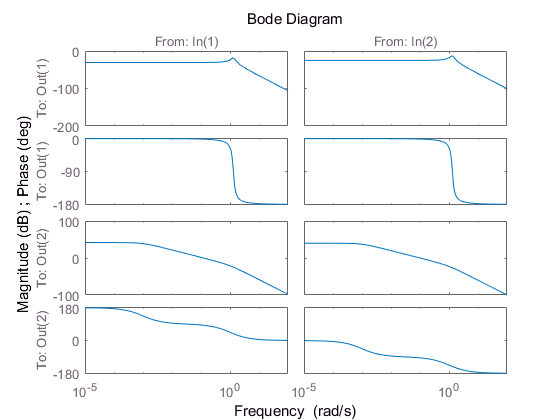

bode(G)

**SISO:**

For G(1,1):

G1 = tf(G(1,1))


G1 =
 
         0.05026
  ----------------------
  s^2 + 0.3249 s + 1.712
 
Continuous-time transfer function.



G1_inv_improper = inv(G1);
G1_inv = G1_inv_improper * 1/(s/100 + 1);
K1  = minreal(Ld * G1_inv)


K1 =
 
  9949 s^2 + 3233 s + 1.703e04
  ----------------------------
          s^2 + 100 s
 
Continuous-time transfer function.



For G(2,2):

G2 = tf(G(2,2))


G2 =
 
           0.1
  ---------------------
  s^2 + 1.001 s + 0.001
 
Continuous-time transfer function.



%G2 = minreal(G2 * s / (s+0.0001));%remove zero poles
G2_inv_improper = inv(G2);
G2_inv = G2_inv_improper * 1/(s/100 + 1);
K2  = minreal(Ld * G2_inv)


K2 =
 
  4998 s^2 + 5005 s + 5
  ---------------------
       s^2 + 100 s
 
Continuous-time transfer function.



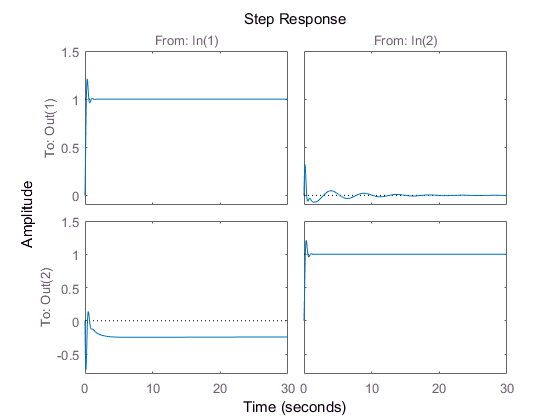

K_loop_siso = [K1 0;0 K2];
L = G * K_loop_siso;
S = inv(eye(2) + L);
T = eye(2) - S;
step(T)

**DIDO:**

Ld_dido = Ld * eye(2);
G_inv_improper = inv(G);
G_inv = G_inv_improper * 1/(s/100 + 1);
K_loop_dido = minreal(Ld_dido * G_inv)


K_loop_dido =
 
  From input 1 to output...
       2976 s^2 + 967 s + 5094
   1:  -----------------------
             s^2 + 100 s
 
       3652 s^2 + 1187 s + 6252
   2:  ------------------------
             s^2 + 100 s
 
  From input 2 to output...
       -2854 s^2 - 2858 s - 2.855
   1:  --------------------------
              s^2 + 100 s
 
       1495 s^2 + 1497 s + 1.496
   2:  -------------------------
              s^2 + 100 s
 
Continuous-time transfer function.



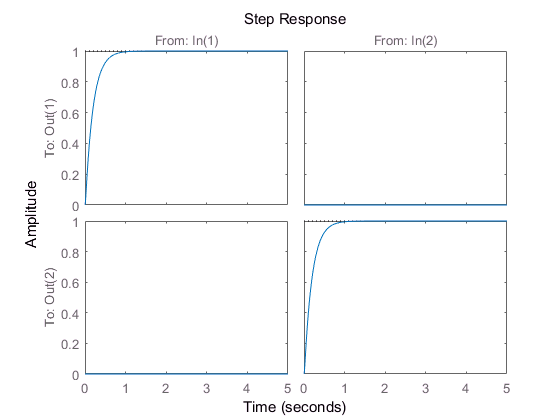

L = G * K_loop_dido;
S = inv(eye(2) + L);
T = eye(2) - S;
step(T)